## PROVA MARKOV CHAIN BANALE

%NON FARE ANDARE, SLEGATO DAL RESTO
%PROVE DI MC; TANTO PER VEDERE COME SONO

initialState = [2000, 3000, 0];

P=[0.6 0.3 0.1;
    0  0.8 0.2;
    0  0   1];

mc=dtmc(P);

mc.StateNames=["young" "old" "died"];

numstates = mc.NumStates;

result=[0 0 0];

numSimulations=1000;

for i = 1:numSimulations
    % Simula la catena di Markov per 1 passo
    X = simulate(mc, 1, 'X0', initialState);  % 1 passo perché X(1) è il primo passo successivo
    sim = X(2,:);  % Prendi lo stato al primo passo successivo
    result(1)=result(1)+sum(sim==1);
    result(2)=result(2)+sum(sim==2);
    result(3)=result(3)+sum(sim==3);
end

result=result/numSimulations;
%figure;
%graphplot(mc, 'ColorEdges', true);

result

result = 1.0e+03 *

    1.2004    3.0003    0.7993



initialState*P

ans =         1200        3000         800



% si avvicina molto al risultato

## RIPRESA DA LAVORO VERO

clear
close all
clc

% cambia path

path = '/Users/Lorenzo/Desktop/Tesi/BankClients.mat';

load BankClients.mat

addpath '/Users/Lorenzo/Desktop/Tesi/TesiVero'

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID

NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end)]; % To use the dummy variables in a model, we must delete a column
            % ABBIAMO DECISO DI TENERE ANCHE L'ULTIMA COLONNA DELLE DUMMY
end

X = [XCat XNum];

mean(BankClients.Age)

ans = 60.4504


std(BankClients.Age)

ans = 21.8224

## GRAFICI DI ANALISI INIZIALI *(si può saltare)*

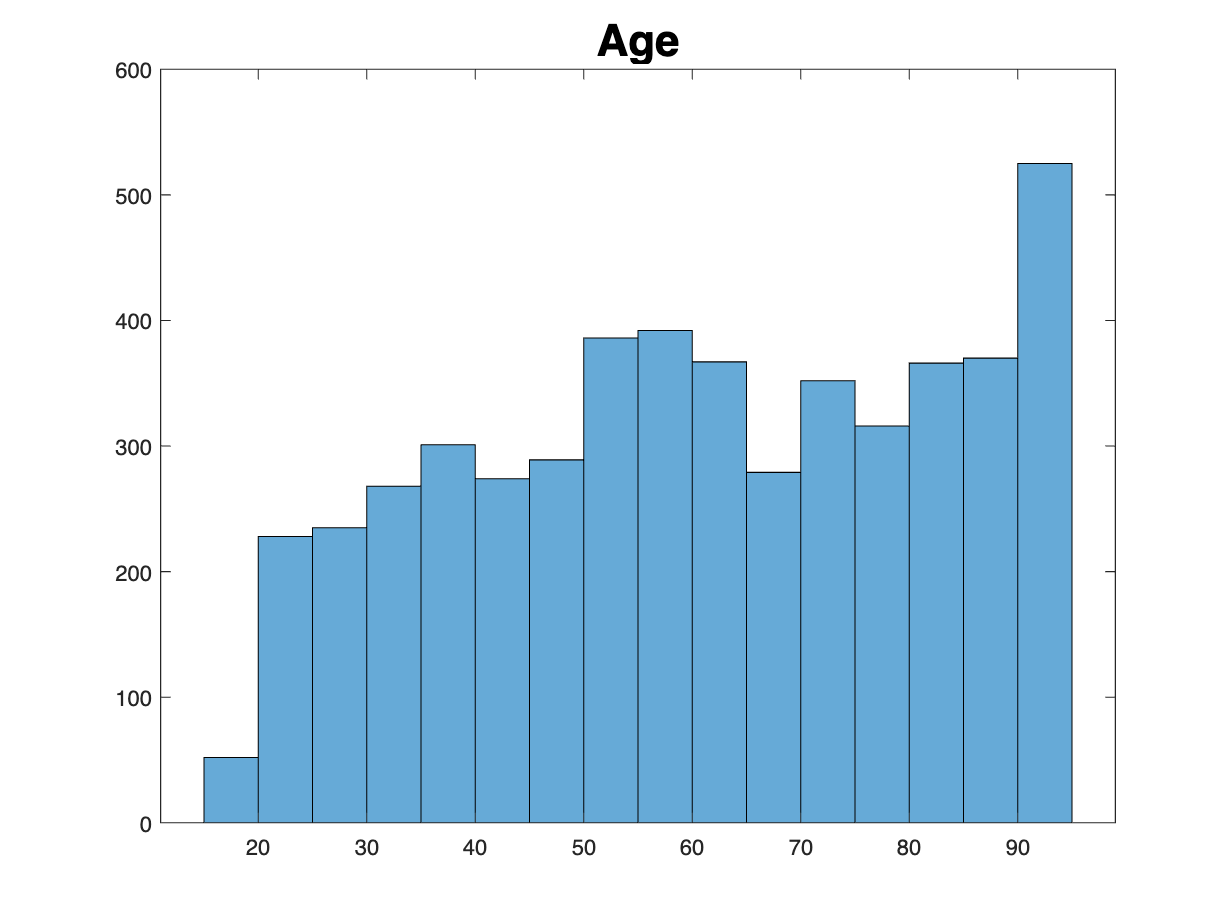

%plots for thesis pies and histograms

histogram(BankClients.Age);
title('Age', FontSize=20);

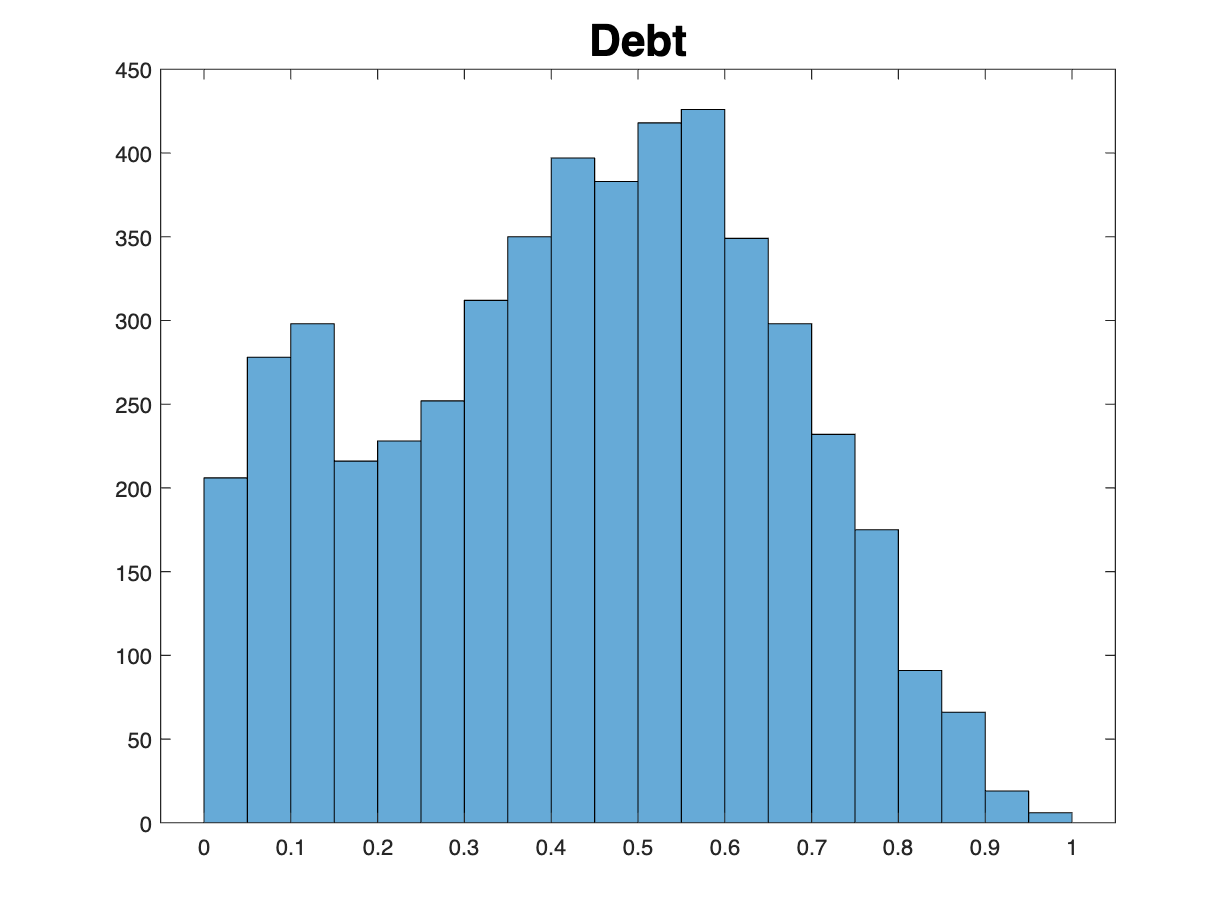


histogram(BankClients.Debt);
title('Debt', FontSize=20);

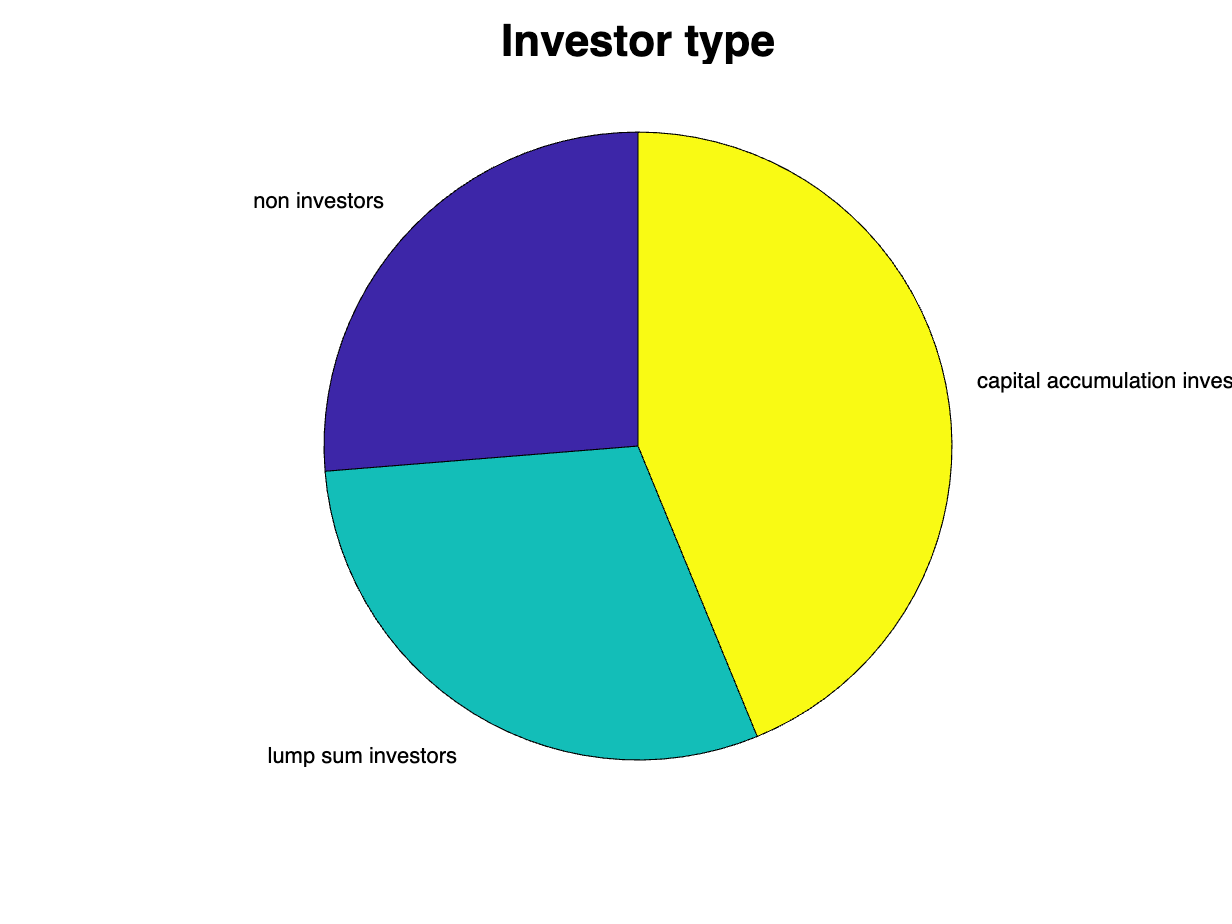


% Contare le occorrenze di ciascuna categoria
InvCounts = countcats(BankClients.Investments);

% Creare il grafico a torta
figure;
pie(InvCounts, {'non investors','lump sum investors','capital accumulation investors'});
title('Investor type',FontSize=20);

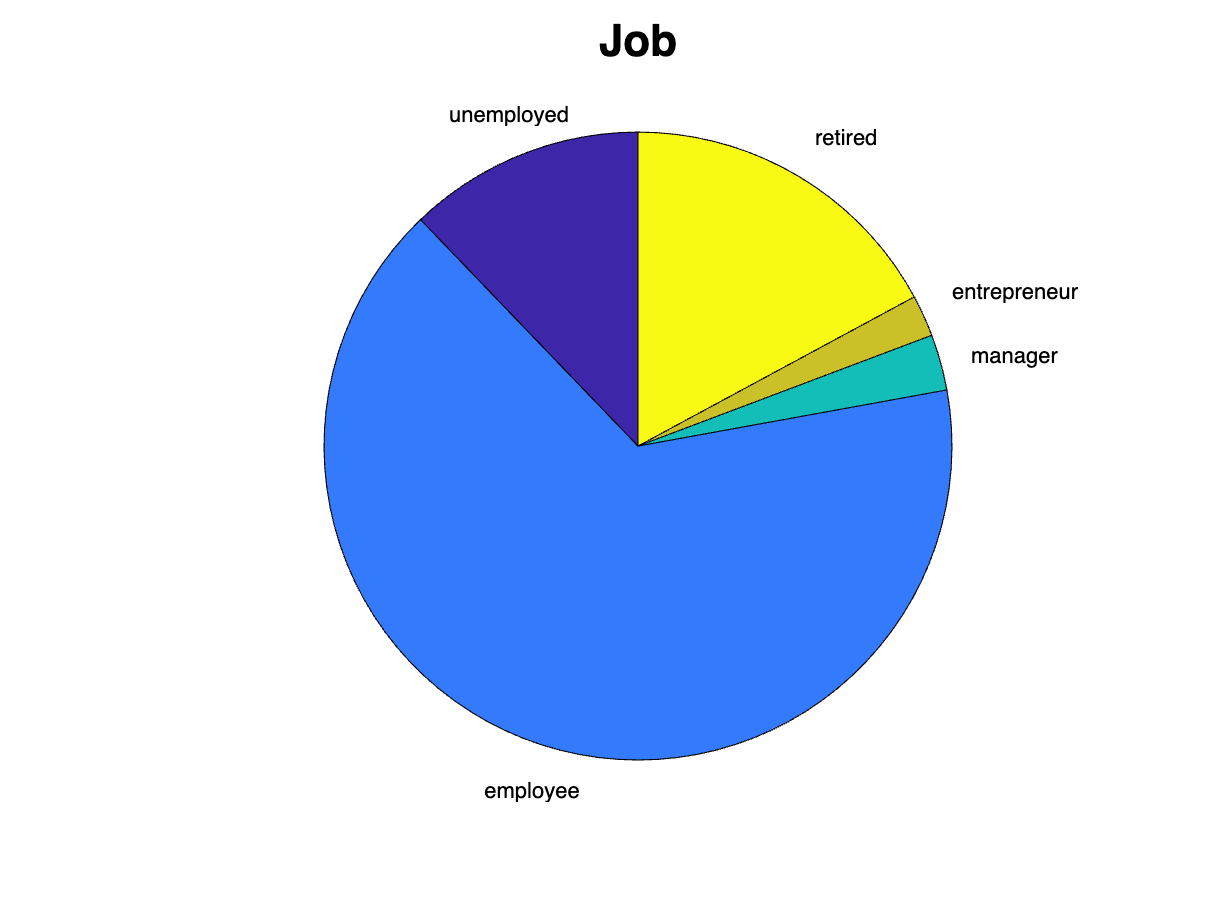

% Contare le occorrenze di ciascuna categoria
JobCounts = countcats(BankClients.Job);

% Creare il grafico a torta
figure;
pie(JobCounts, {'unemployed','employee','manager','entrepreneur','retired'});
title('Job',FontSize=20);

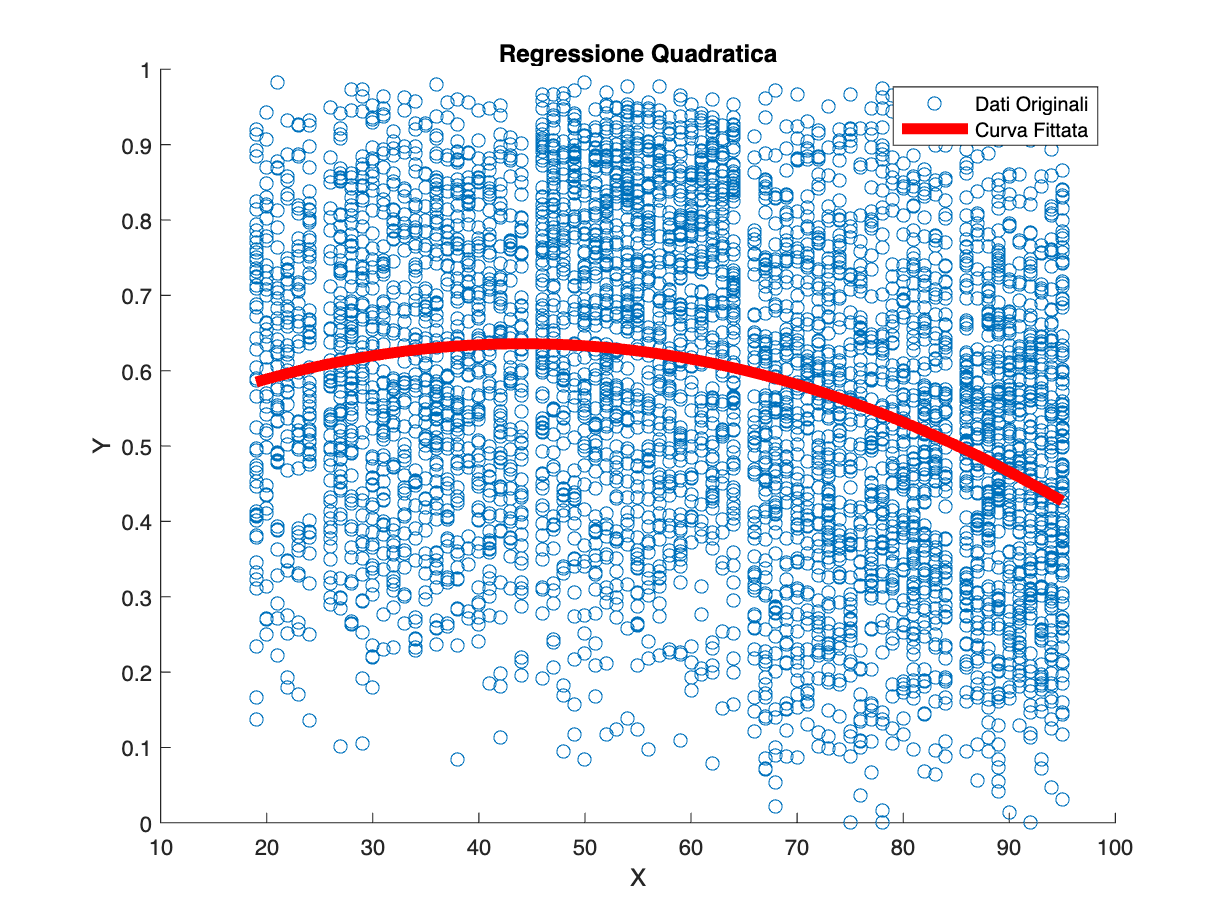

% voglio capire come procede l'income:

x=BankClients.Age;

y=BankClients.Income;

% Fitta una regressione quadratica (polinomio di secondo grado)
p = polyfit(x, y, 2);

% p contiene i coefficienti del polinomio fittato: [p1, p2, p3]
% y = p1*x^2 + p2*x + p3

age_distinct=min(x):max(x);

% Valuta il polinomio sui dati originali
y_fit = polyval(p, age_distinct);

% Plot dei dati originali e della curva fittata
figure;
scatter(x, y, 'o'); % Dati originali
hold on;
plot(age_distinct, y_fit, '-r', 'LineWidth', 5); % Curva fittata
xlabel('X');
ylabel('Y');
title('Regressione Quadratica');
legend('Dati Originali', 'Curva Fittata');
hold off;

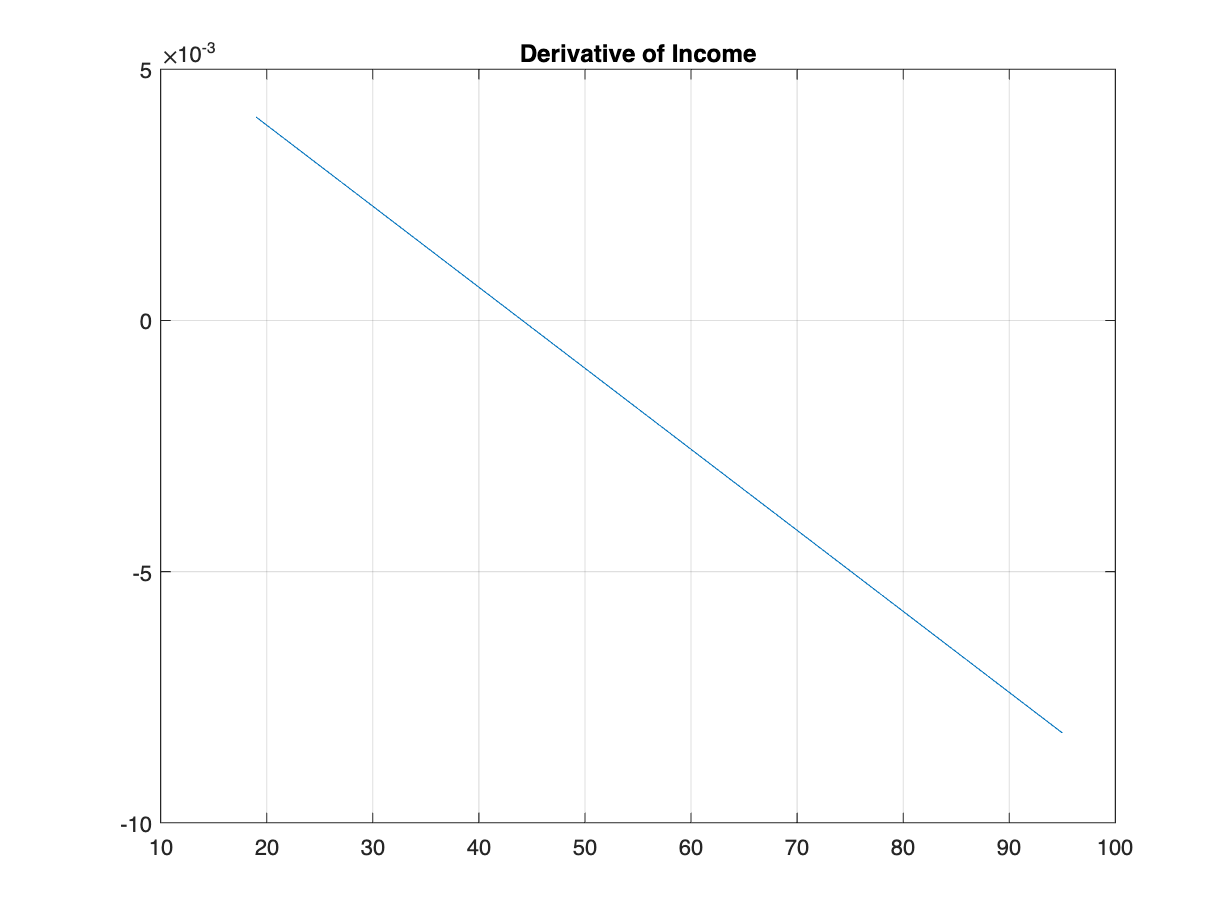

% calcolo la derivata della curva nei punti, credo possa darmi un'idea 
% buona di media della variazione gaussiana di income che mi servirà nei
% modelli


% Derivata del polinomio
p_deriv = polyder(p);

% Valutazione della derivata nei punti specificati
income_slope = polyval(p_deriv, age_distinct);

% Mostrare i risultati
plot(age_distinct, income_slope);
title('Derivative of Income');
grid on;

% Ottieni l'ultimo elemento
last_slope = income_slope(end);

% Crea un vettore con dieci copie dell'ultimo elemento
repeated_last = repmat(last_slope, 1, 15);

% Concatenalo con il vettore originale
income_slope = [income_slope, repeated_last];


## DISTANZE E CLUSTERS

% prove con le distanze; se uso pdist viene diversa dalla distanza normale

D2 = pdist(X, @MixDistanceL2copia); 
%D1 = pdist(X, @MixDistanceL1copia); 

% vedo le forme quadrate per capire a quali punti si riferiscono

%D1sq=squareform(D1);
D2sq=squareform(D2);

% non so perchè ma fare pdist o chiamare direttamente la funzione cambia

%D1prova=MixDistanceL1copia(X,X);
D2prova=MixDistanceL2copia(X,X);

average2 = linkage(D2, "average");
c_average2 = cophenet(average2,D2);  % migliore, 0.8992

% nel lavoro della Vero son state provate tutte, io ho messo direttamente
% quella che lì risulta la migliore


T6 = cluster(average2,'maxclust',6);

C1 = BankClients(T6==1,:);
C2 = BankClients(T6==2,:);
C3 = BankClients(T6==3,:);
C4 = BankClients(T6==4,:);
C5 = BankClients(T6==5,:);
C6 = BankClients(T6==6,:);

% tutti loro hanno un solo valore di investmets: i primi due 2, terzo e
% quarto 3, gli ultimi 1



% ho i cluster e chi ne fa parte;
% calcolo come fare un summary della Personas, 
% uso moda per categoriche e media per numeriche

center1=compute_center(C1);
center2=compute_center(C2);
center3=compute_center(C3);
center4=compute_center(C4);
center5=compute_center(C5);
center6=compute_center(C6);

centers=[center1.'; center2.'; center3.'; center4.';...
    center5.'; center6.'];

% non capisco perchè ma devo togliere 1 al gender

centers(:,3)=centers(:,3)-1;


% con la funzione calcolo il cluster di appartenenza vedendo 
% a quali centri sono più vicini i punti

clust=compute_new_cluster(BankClients, centers);

% vediamo se corrispondono ai cluster scelti

diff_clusters = T6~=clust;

sum(diff_clusters)

ans = 108

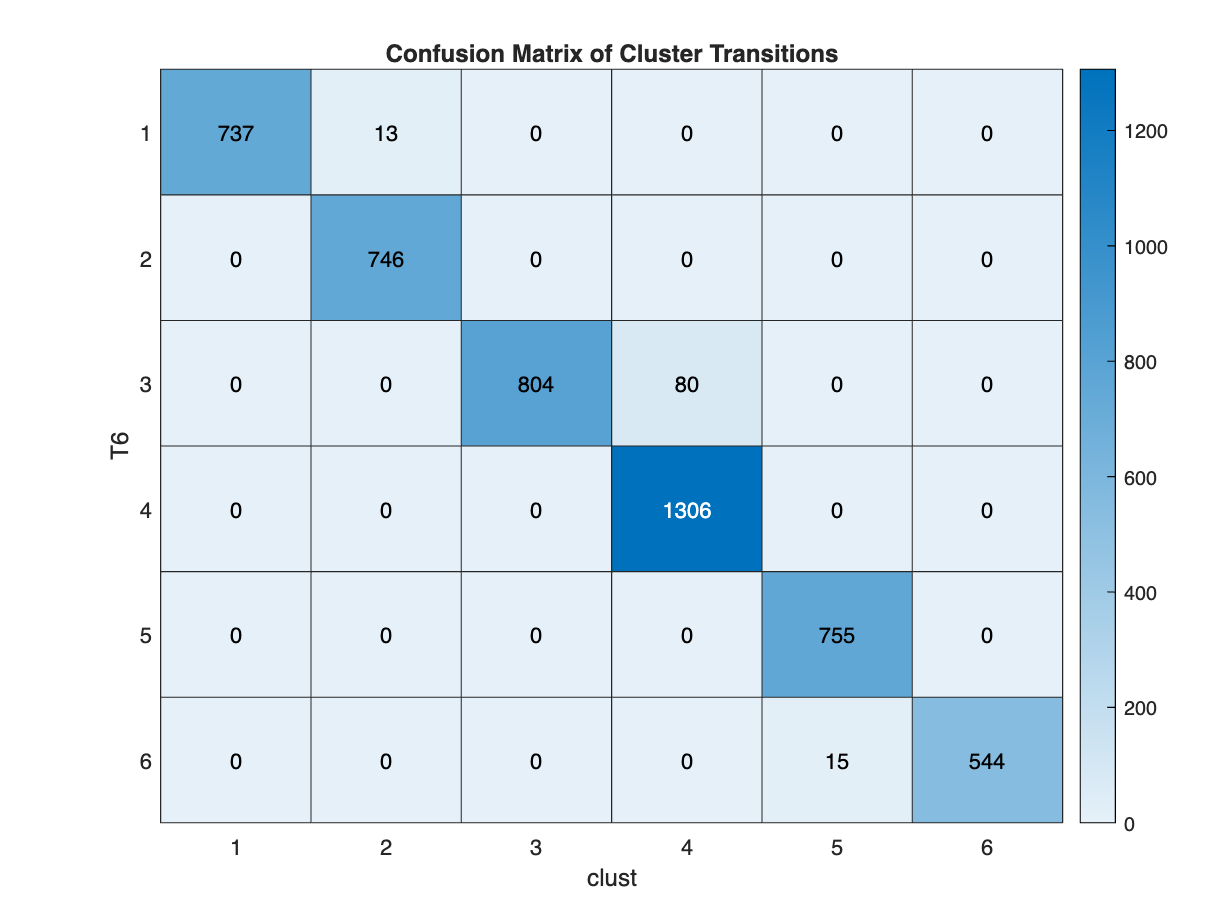

% su 5000 solo 108 differiscono, buono 
% direi che posso procedere e tenerli così, considerando che 
% il centro dei cluster più vicino e il clustering originale 
% fanno la stessa cosa

% Crea la matrice di confusione
conf_matrix = confusionmat(clust, T6);

% Visualizza la matrice di confusione
figure;
heatmap(conf_matrix, 'XLabel', 'clust', 'YLabel', ...
    'T6', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});

% con la funzione calcolo il cluster di appartenenza vedendo 
% a quali centri sono più vicini i punti
BankClients_noinv=BankClients;
BankClients_noinv.Investments=categorical(zeros(5000,1));

centers_noinv=centers;
centers_noinv(:,18)=zeros(6,1);

clust_noinv=compute_new_cluster(BankClients_noinv, centers_noinv);
% NON IL MODO CORRETTO: IL MODO GIUSTO è METTERE 0 NEL COEFFICIENTE DI INV
% NELLA FUNZIONE compute_new_cluster_coeffinv, CHE PERMETTE DI
% COSTUMIZZARLO (NELL'ALTRA FUNZIONE è A 8)


% vediamo se corrispondono ai cluster scelti

diff_clusters= T6~=clust_noinv;

sum(diff_clusters)

ans = 3603

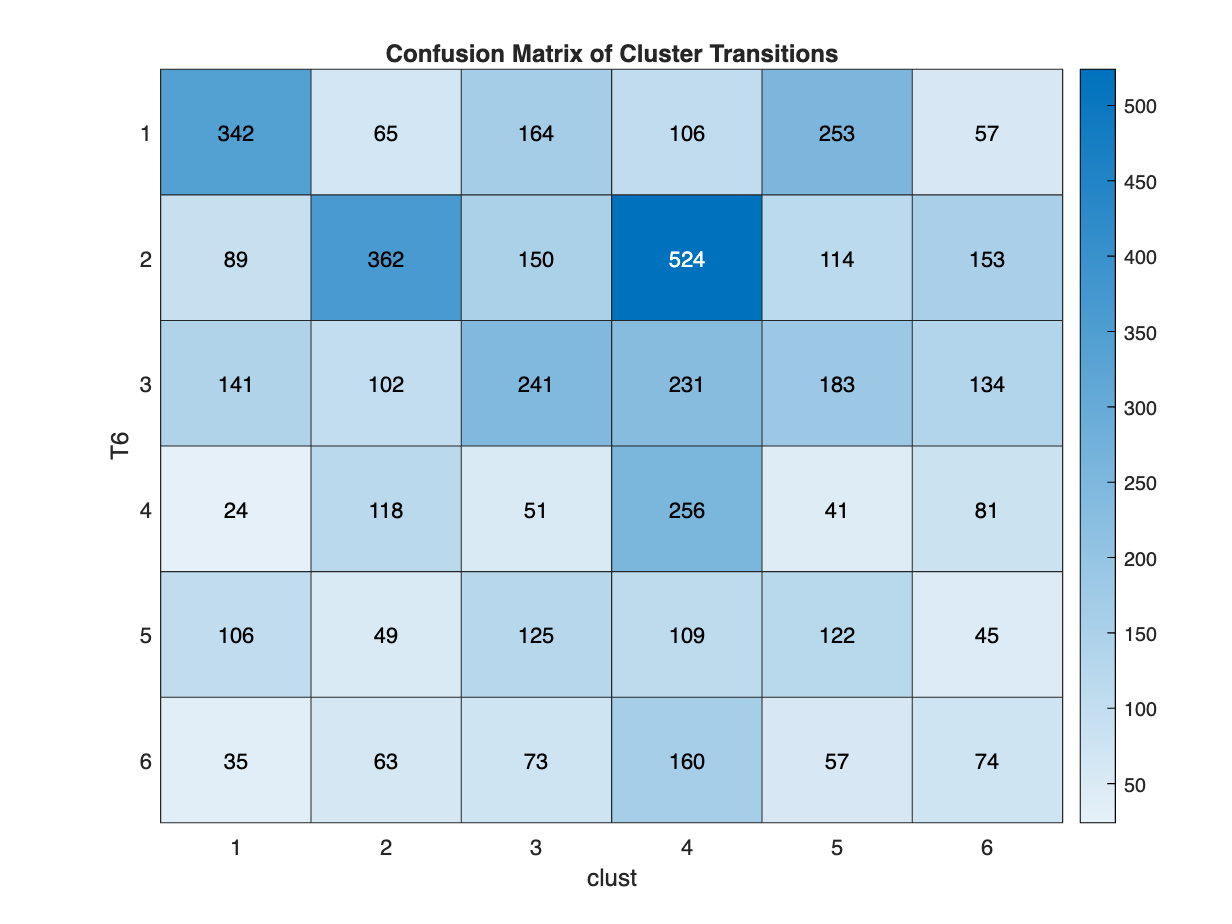

% su 5000 3603 differiscono, brutto segno
% direi che posso procedere e tenerli così, considerando che 
% il centro dei cluster più vicino e il clustering originale 
% fanno la stessa cosa

% Crea la matrice di confusione
conf_matrix_noinv = confusionmat(clust_noinv, T6);

% Visualizza la matrice di confusione
figure;
heatmap(conf_matrix_noinv, 'XLabel', 'clust', 'YLabel', ...
    'T6', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});

## PROBABILITÀ DI MORTE NEI PROSSIMI 5 ANNI DEL CLIENTE

Basandoci sull'età prendiamo i dati sulla mortalità dal database mondiale per un perido recente (precovid, dato che il covid è considerato una situazione straordinaria rispetto a quello che vogliamo stimare noi) in Italia.

Aggiungeremo un cluster che è quello dei deceduti, corrispondente al numero 0.


% IMPORTO I DATI SULLA MORTALITÀ

fem_mort = readcell('females_mortality5x1.txt', 'NumHeaderLines',1);
men_mort= readcell('male_mortality5x1.txt', 'NumHeaderLines',1);

% tengo i dati che mi interessano, 2018
fem_mort=fem_mort(3532:3551,2:4);
men_mort=men_mort(3532:3551,2:4);


% creo due nuove colonne con  minimo e massimo di età di ogni range

fem_mort=string(fem_mort);
men_mort=string(men_mort);

for i=1:size(men_mort,1)
    age_range_str=string(fem_mort(i,1));
    range_parts = strsplit(age_range_str, '-');

    fem_mort(i,1)=range_parts(1,1);
    fem_mort(i,2)=range_parts(1,2);
    men_mort(i,1)=range_parts(1,1);
    men_mort(i,2)=range_parts(1,2);
end


% qui calcolo con che probabilità la gente è morta

T_5y=[T6, T6];

fem_mort=double(fem_mort);
men_mort=double(men_mort);

% uso la funzione sotto per simulare le morti 

% contiene 1 se sono vivi fra 5 anni, 0 altrimenti: basta fare la
% moltiplicazione elementwise per avere il risultato di un sample dalle
% prob di morte

alive_5y=get_death_probability(Data.Age, double(Data.Gender),fem_mort,men_mort);

T_5y(:,2)=alive_5y.*T_5y(:,2);


## INIZIAMO A FARE PROVE; MODIFICO I CLIENTI E VEDO SE STANNO NEI CLUSTER (SOLO ETà)

%1° TENTATIVO: variare solo età in età+5

BankClients5y=BankClients;
BankClients5y.Age=BankClients5y.Age+5;

clust5y=compute_new_cluster(BankClients5y, centers);
% tengo i centri inalterati, supponendo che rappresentino il tipo di
% personas e che sia una cosa che non varia nel tempo

%aggiungiamo i morti
clust5y_withdeath=clust5y.*alive_5y;

evolved=clust~=clust5y;

T_jumped=[clust(evolved), clust5y(evolved)];

%T_jumped(T_jumped(:,1) == 1, :);
%T_jumped(T_jumped(:,1) == 3, :);  con questi si nota subito che nessun
%elemento è migrato dai 3 cluster di vecchi ad altri
%T_jumped(T_jumped(:,1) == 5, :);

%T_jumped(T_jumped(:,2) == 2, :);
%T_jumped(T_jumped(:,2) == 4, :);  con questi si nota subito che nessun
%elemento è migrato ai 3 cluster di giovani da altri
%T_jumped(T_jumped(:,2) == 5, :);

% con questo modello gli elementi non saltano da un cluster di vecchi ad un
% altro e nemmeno da un cluster di giovani a un altro

sum(evolved) % numero di persone che hanno cambiato cluster solamente

ans = 371

% modificando la loro età (nulla di casuale tutto deterministico), 371 non
% sono poche, 7percento


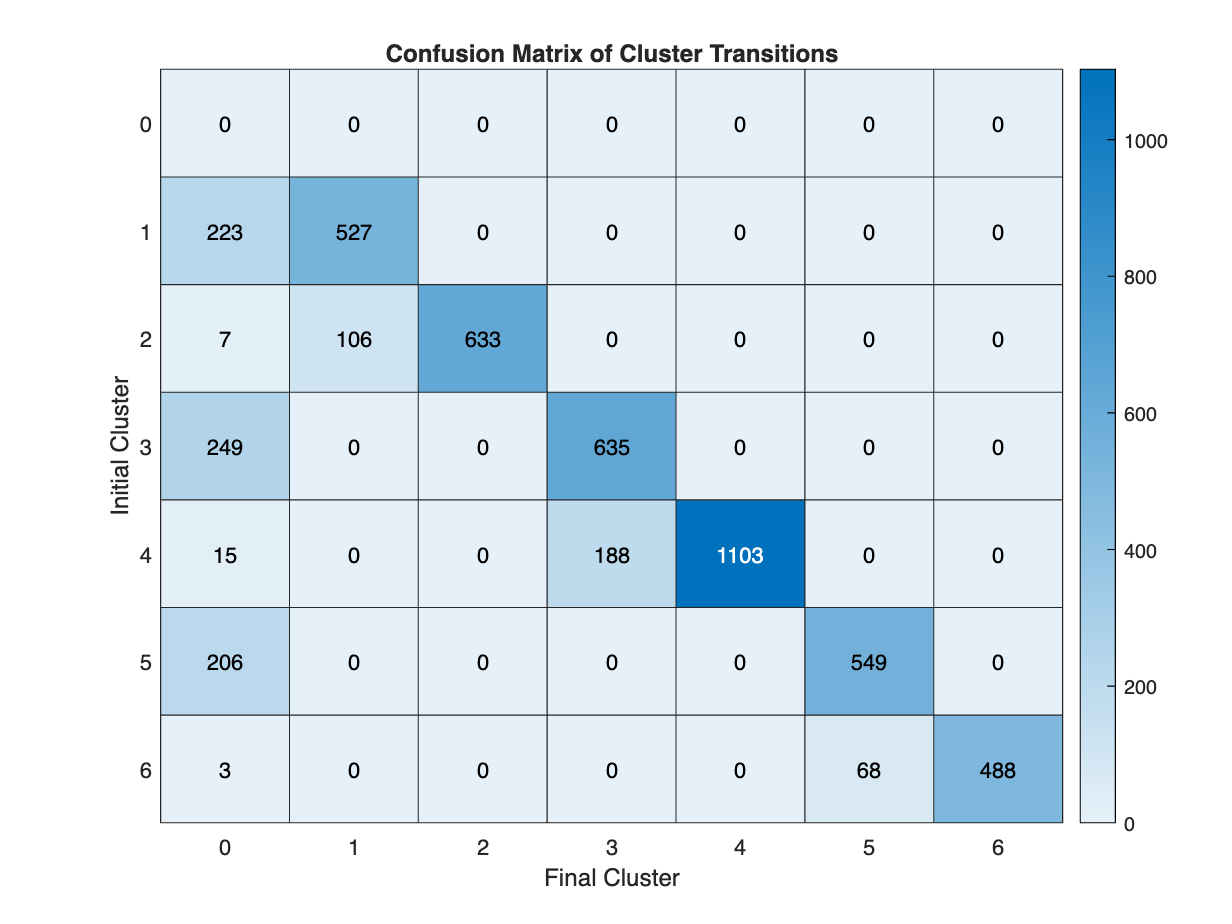

% Crea la matrice di confusione
confusion_matrix = confusionmat(clust, clust5y_withdeath);

% Visualizza la matrice di confusione
figure;
heatmap(confusion_matrix, 'XLabel', 'Final Cluster', 'YLabel', ...
    'Initial Cluster', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'0', '1', '2','3','4','5','6'},...
    'YDisplayLabels', {'0', '1', '2','3','4','5','6'});


% saltano solamente da 2 a 1 o da 4 a 3 o da 6 a 5, cioè ogni custer
% vecchio ne ha uno giovane corrispondente e "attinge" da lì esclusivamente

% naturalmente muoiono molto più nei cluster vecchi che in quelli nuovi,
% ~650 contro ~25


%2° TENTATIVO: variare età in età+5 e savings (COME????)

rng(1997);

gauss_savings=sqrt(0.1)*randn(5000,1)+0.1;  
% quello che metto dentro sqrt è la varianza della gaussiana

mean(gauss_savings)

ans = 0.1040


var(gauss_savings)

ans = 0.0983


BankClients_5y_svngs=BankClients;
%BankClients_5y_svngs.Age=BankClients_5y_svngs.Age+5;
BankClients_5y_svngs.Income=BankClients_5y_svngs.Income+gauss_savings;
BankClients_5y_svngs.Wealth=BankClients_5y_svngs.Wealth+gauss_savings;
BankClients_5y_svngs.Saving=BankClients_5y_svngs.Saving+gauss_savings;

clust_5y_svngs=compute_new_cluster(BankClients_5y_svngs, centers);

%aggiungiamo i morti
clust_5y_svngs_dth=clust_5y_svngs.*alive_5y;

evolved=clust~=clust_5y_svngs_dth;

sum(evolved)

ans = 705

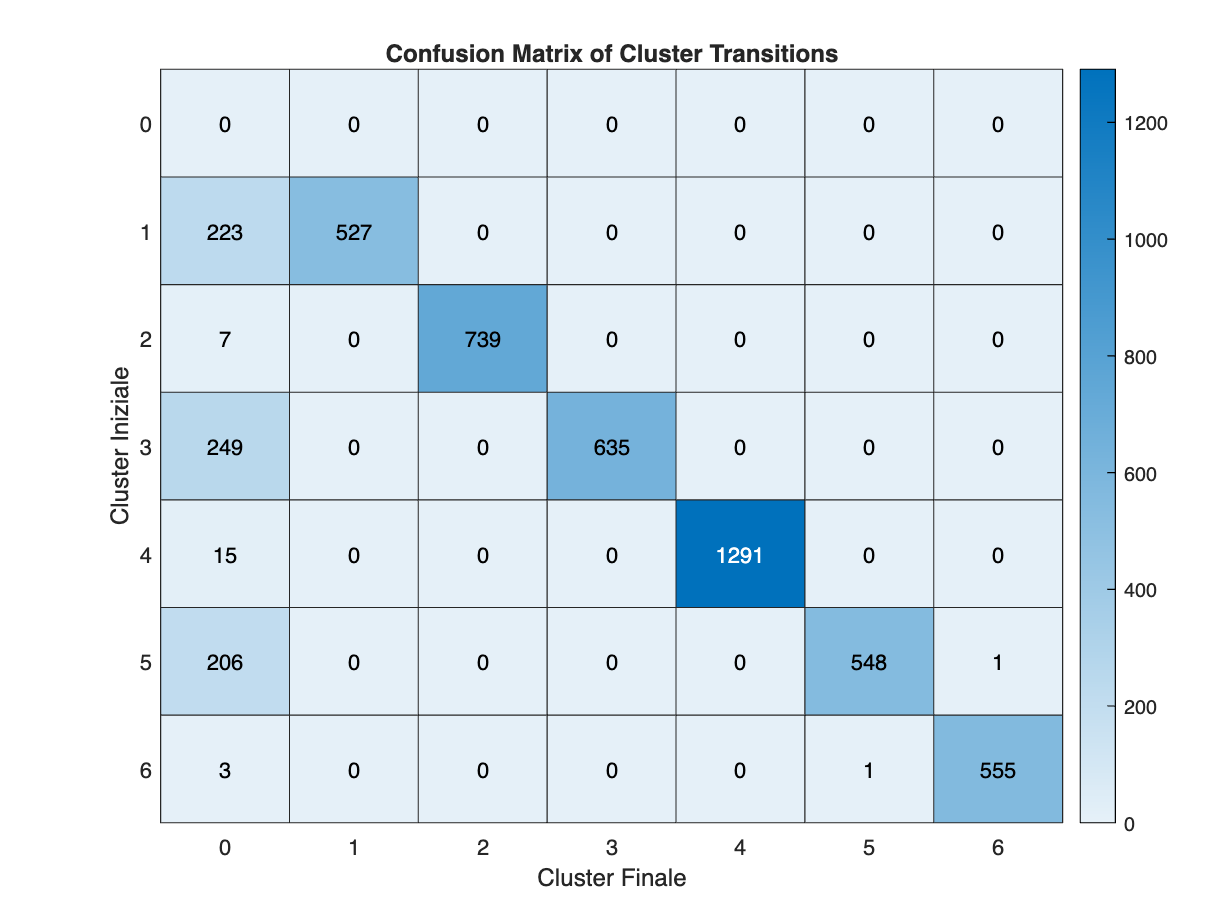


% Crea la matrice di confusione
confusion_matrix = confusionmat(clust, clust_5y_svngs_dth);

% Visualizza la matrice di confusione
figure;
heatmap(confusion_matrix, 'XLabel', 'Cluster Finale', 'YLabel', ...
    'Cluster Iniziale', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'0', '1', '2','3','4','5','6'},...
    'YDisplayLabels', {'0', '1', '2','3','4','5','6'});

Il problema maggiore è che con il peso che abbiamo dato all'Investor Type nel calcolo della metrica ora gli elementi non escono più da quella cateogria, anche cambiando tantissimo le altre features senza cambiare quello non si muovono. Posso fare un'ipotesi: tolgo il tipo di investitore a senza quello (distanza uguale da tutti i centri se si guarda solo l'Investment) vedo dove vanno; mi aspetto molto più mescolamento, e per prima cosa vedo come sarebbero valutati i cluster iniziali nel caso fosse sconosciuto il tipo di investitori.

% nuovo approccio da provare; stimo probabilità o vicinanza ai nuovi centri
% diminuendo il valore di investor type;
% creo la funzion MixDIstanceL2copia_coeffinv per poter modificare il
% parametro di peso della variabile Investitore

% con la funzione calcolo il cluster di appartenenza vedendo 
% a quali centri sono più vicini i punti

clust_coeff_changed=compute_new_cluster_coeffinv(BankClients, centers, 1);

% vediamo se cambiano rispetto ai cluster iniziali con coeff=8

diff_clusters = clust~=clust_coeff_changed;

sum(diff_clusters)

ans = 251

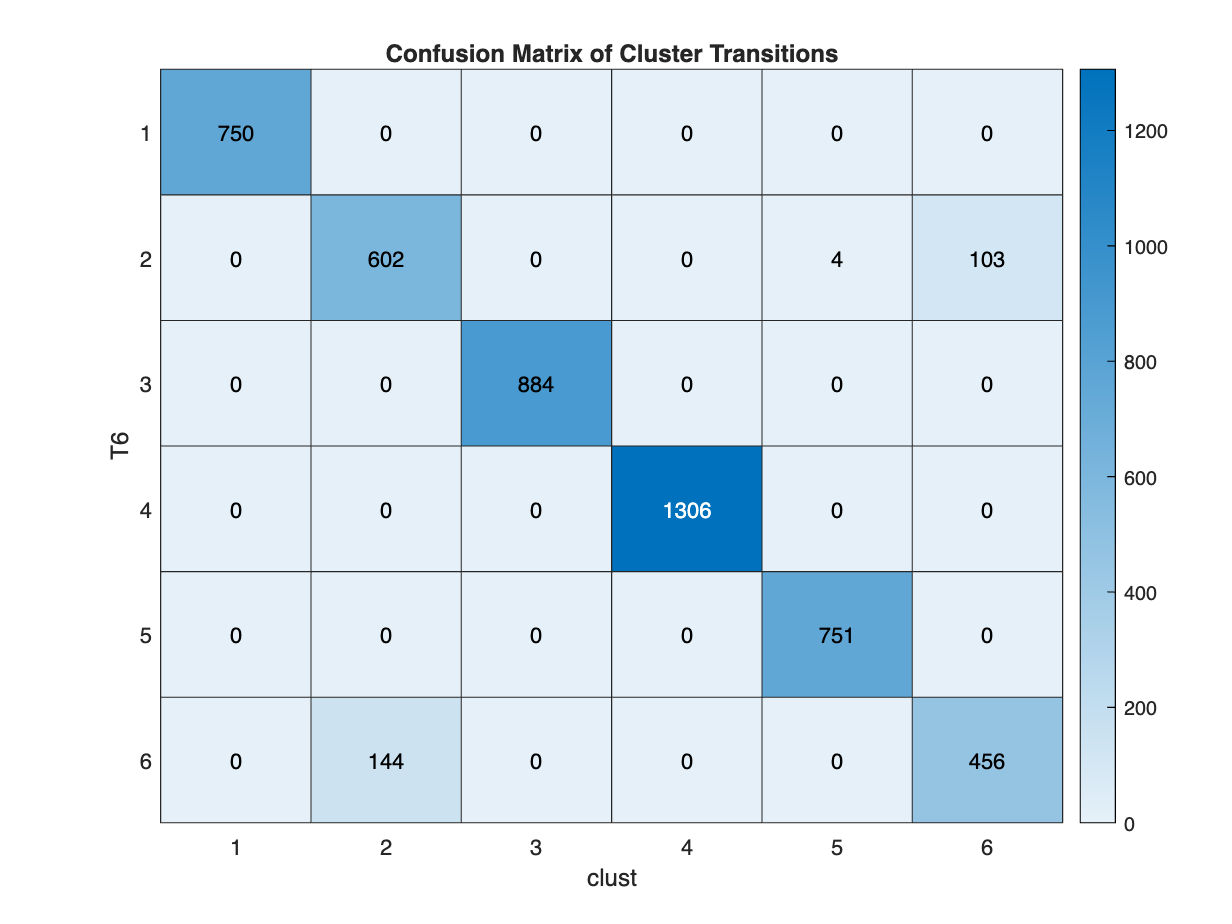

% 3232/5000 differiscono; tantissimi, in pratica il tipo di Investment
% faceva nel creare i cluster

% Crea la matrice di confusione
conf_matrix_coeff_changed = confusionmat(clust_coeff_changed, clust);

% Visualizza la matrice di confusione
figure;
heatmap(conf_matrix_coeff_changed, 'XLabel', 'clust', 'YLabel', ...
    'T6', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});

Cosa cambia? va "a scacchiera": le età più o meno dividono i cluster in 1, 3 e 5 (vecchi) e 2, 4 e 6 (giovani); se tolgo l'Investment come caratteristica (che pesava più di tutto il resto), mi rimane che i giovani saltano ad altri giovani e i vecchi ad altri vecchi, ma praticamente tra le due categore non ci sono distinzioni. 

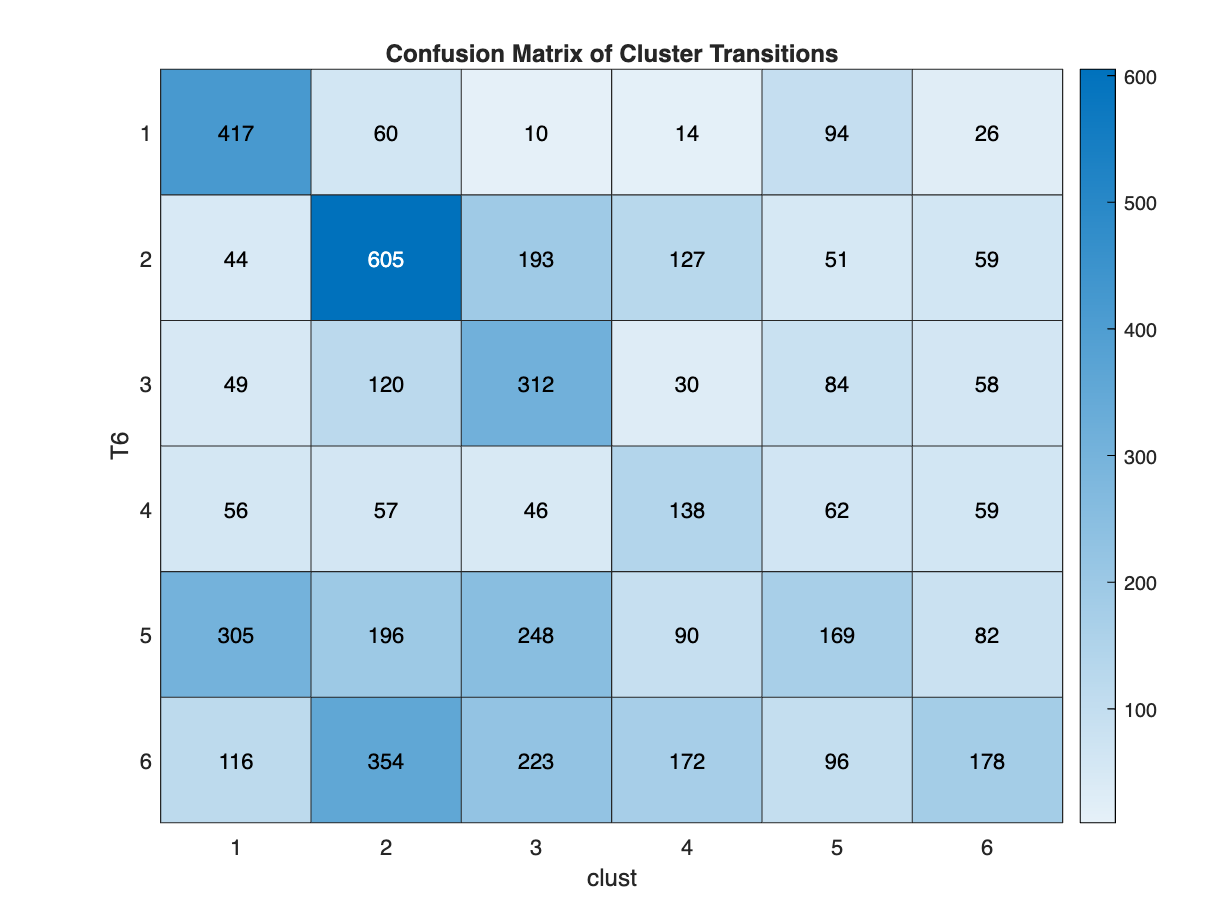

% come mai c'è differenza con il caso in cui metto a 0 tutti gli Inv in
% clust? vediamo la confusion matrix

clust_coeffinv_0=compute_new_cluster_coeffinv(BankClients, centers, 0);

% Crea la matrice di confusione
conf_matrix_compare = confusionmat(clust_coeffinv_0, clust_noinv);

% Visualizza la matrice di confusione
figure;
heatmap(conf_matrix_compare, 'XLabel', 'clust', 'YLabel', ...
    'T6', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});

C'è differenza perchè nei due casi hanno pesi diversi le categoriche, essendo che tolgo 3 al peso delle categoriche (avendo in teoria 3 colonne di investements quando passo alle dummy) ma quando ho messo gli investimenti a 0 non ne ho più 3; il metodo più corretto mi pare essere quello di dire che fccio il conto di tutto e poi metto a 0 il peso di investments, così la struttura è uguale fino alla fine.

## TENTATIVO CON COEFFICIENTE DI INVESTMENTS "EVANESCENTE"

Idea: posso pensare di fare tante simulazioni con il coefficiente che tende verso l'insignificanza, e vedere poi i risultati di come sono clusterizzati i clienti.

PROBLEMA: al momento ho calcolato le distanze con pdist, e quindi non posso mettere come parametro il coefficiente di Investments, perchè pdist non accetta distanze con parametri.

TROVATO IL MODO [https://stackoverflow.com/questions/35798076/matlab-passing-parameters-to-pdist-custom-distance-function](https://stackoverflow.com/questions/35798076/matlab-passing-parameters-to-pdist-custom-distance-function)

RISOLTO CON QUESTO

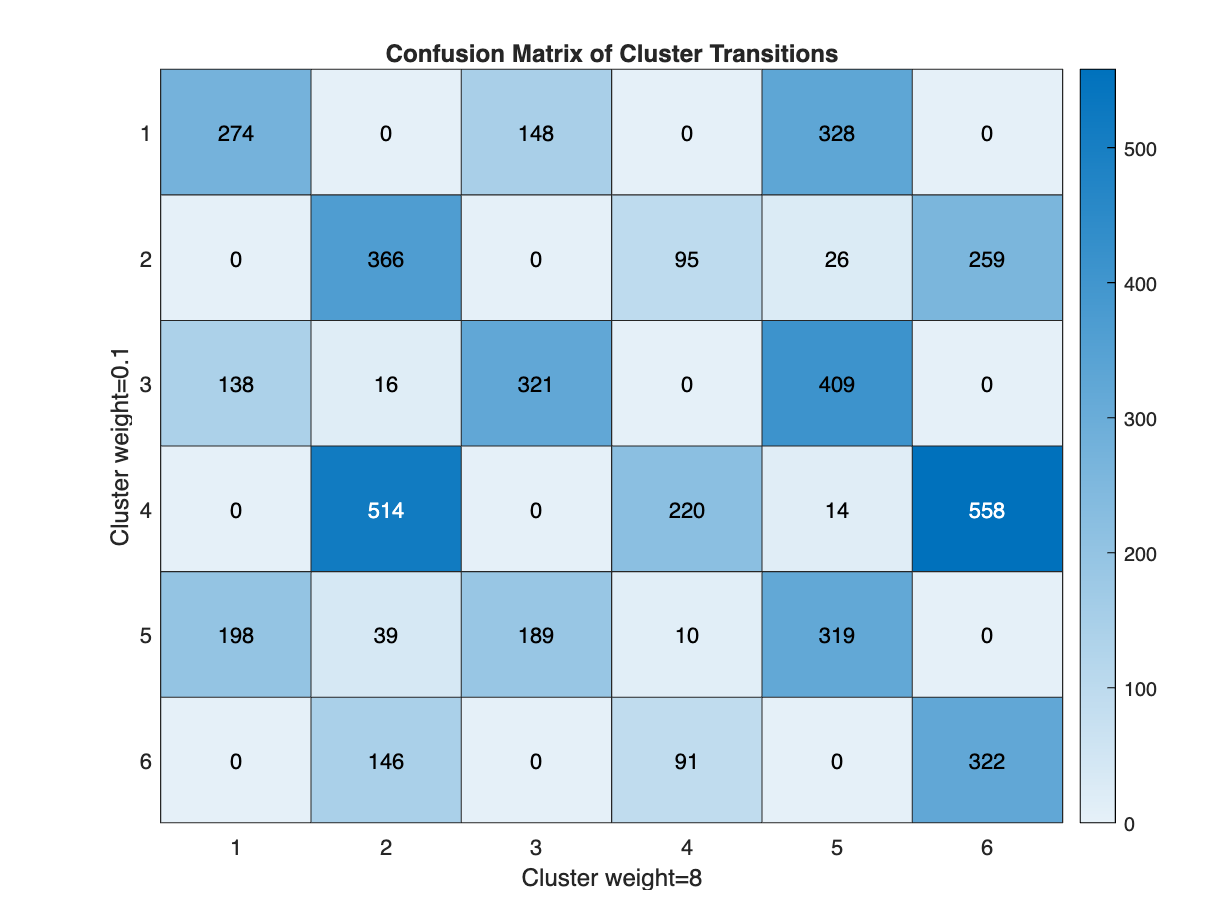

T_weighted=compute_new_cluster_coeffinv(BankClients, centers, 0.01);

% compariamo con l'originale, cambiando vari pesi del coefficiente

% Crea la matrice di confusione
conf_matrix_comp = confusionmat(clust, T_weighted);

% Visualizza la matrice di confusione
figure;
heatmap(conf_matrix_comp, 'XLabel', 'Cluster weight=8', 'YLabel', ...
    'Cluster weight=0.1', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});

## Evolution in time: POSSIBILITIES

- **Age: **will change deterministically (if the jump between states is of one year +1, if five years +5 ecc.)

- **Gender: **NEVER CHANGE (both because it is difficult to change, both because from Veronica's work we saw it doesn't influence clusters that much)

- **Job: TO BE DEFINED**

- **Area: **Probably not changing

- **CitySize: **Probably not changing

- **FamilySize: **NEVER CHANGE (because from Veronica's work we saw it doesn't influence clusters that much)

- **Income: **can change maybe depending on age, or on age+job

- **Wealth: **

- **Debt: **

- **FinEdu:**

- **ESG:**

- **Digital:**

- **BankFriend:**

- **LifeStyle:**

- **Luxury:**

- **Saving:**

- **Investments: **most difficult to treat; if i want to evaluate if people changes, I must give it a small weight and see the center it becomes near, and suppose the client has switched to that kind of investor. Maybe I can differentiate those who changes investements and those who mantain them, supposing they are 100% that kind of investors, differently from the first ones mentioned. 

#### V1 DETERMINISTIC (AGE + 1,2,3,....,10)

Age aumented by 1 year at a time, deterministic change. We also multiply the coefficient of Investement by a vanishig term, because the idea is that we know for sure the invesor type at year 0, but then it changes.

BankClients_age=BankClients;
progr_clusts = zeros(5000, 10);

inv_coeff=8;

tot_years=10

tot_years = 10


for yrs=1:tot_years
    BankClients_age.Age=BankClients_age.Age+1;
    progr_clusts(:,yrs)=compute_new_cluster_coeffinv(BankClients_age, centers, inv_coeff/(2^yrs));
end

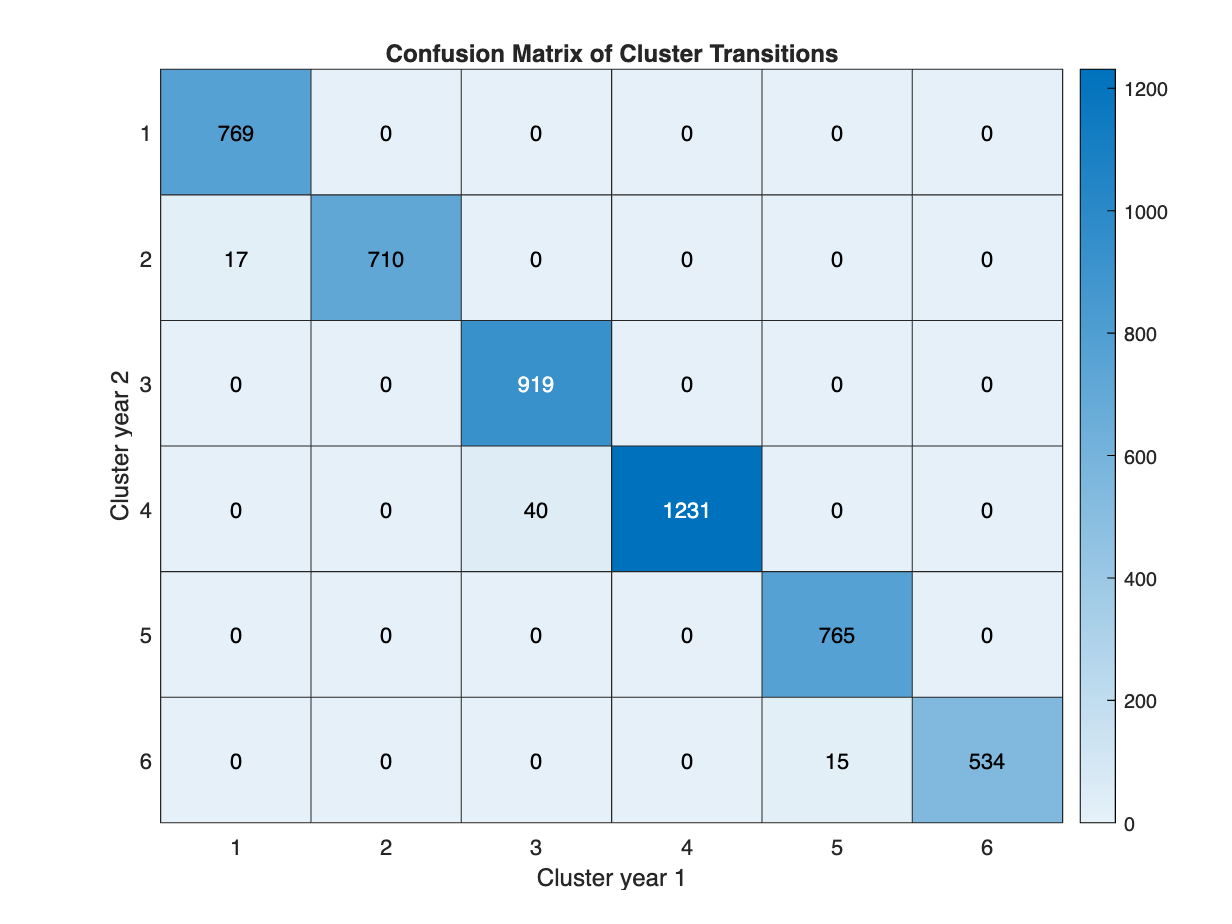

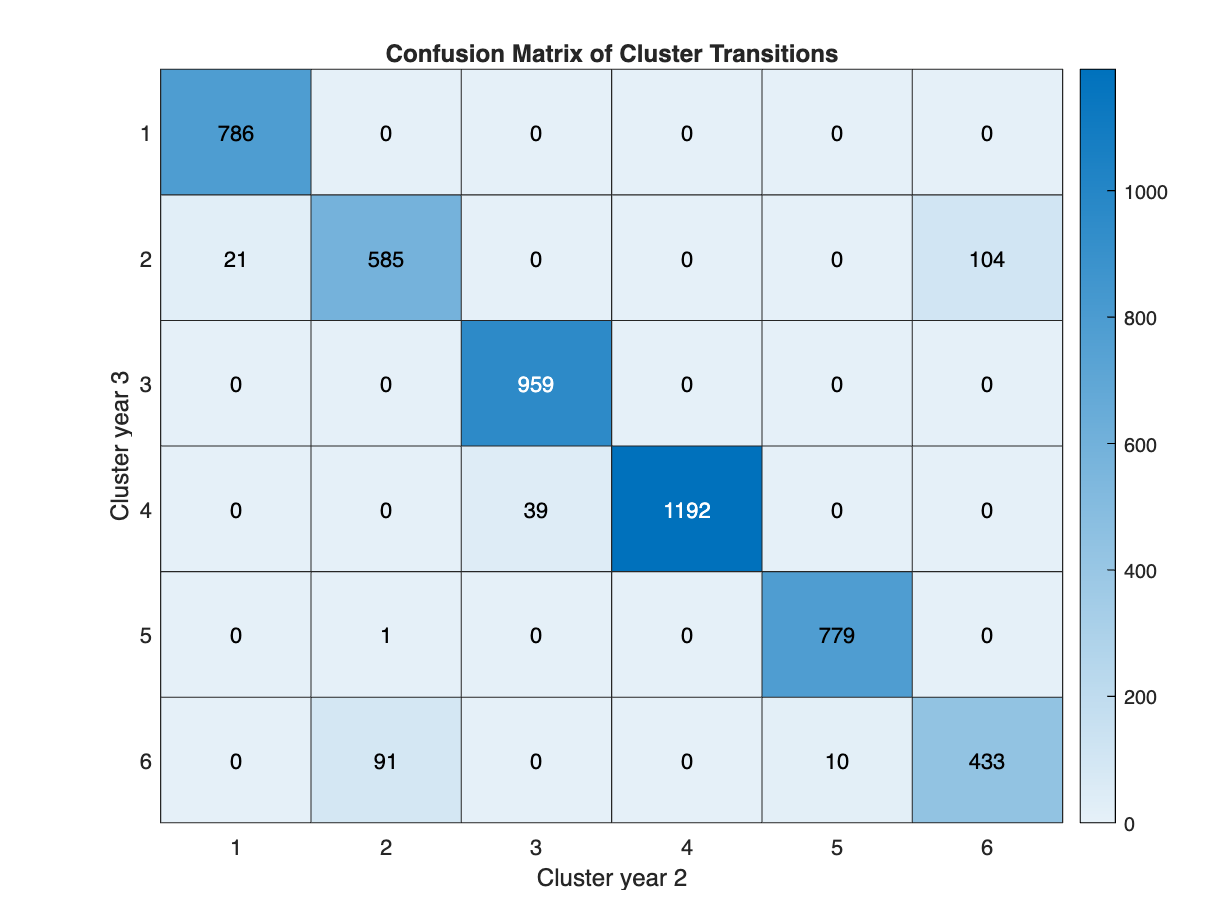

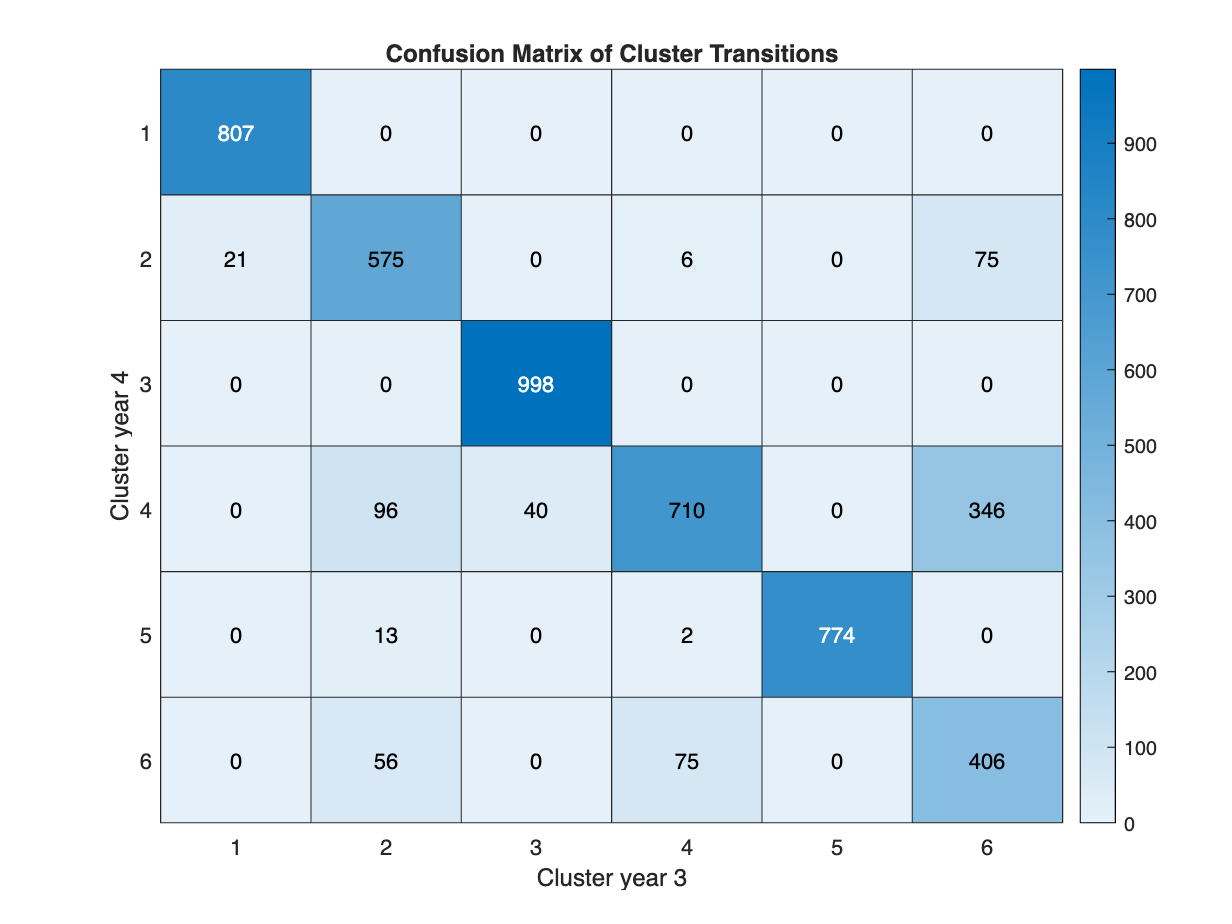

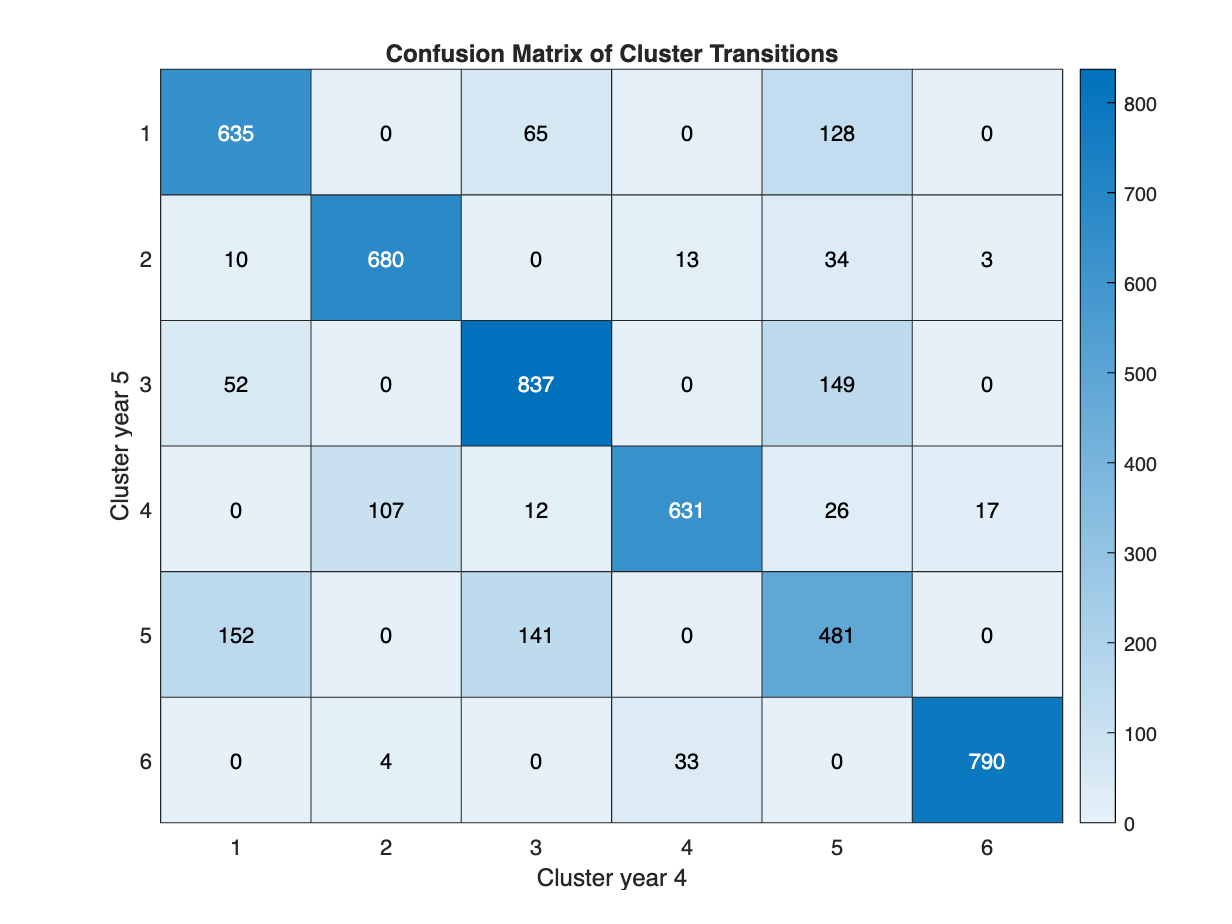

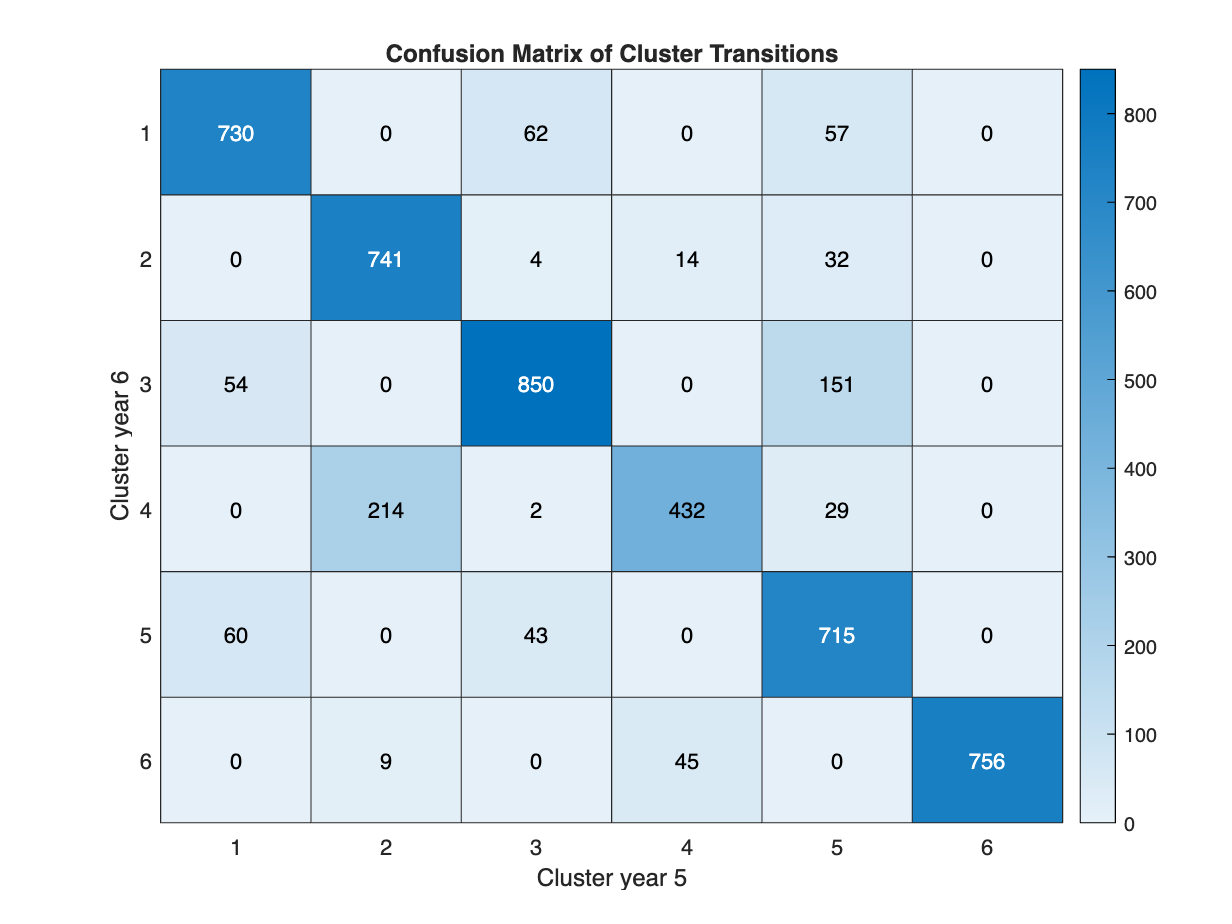

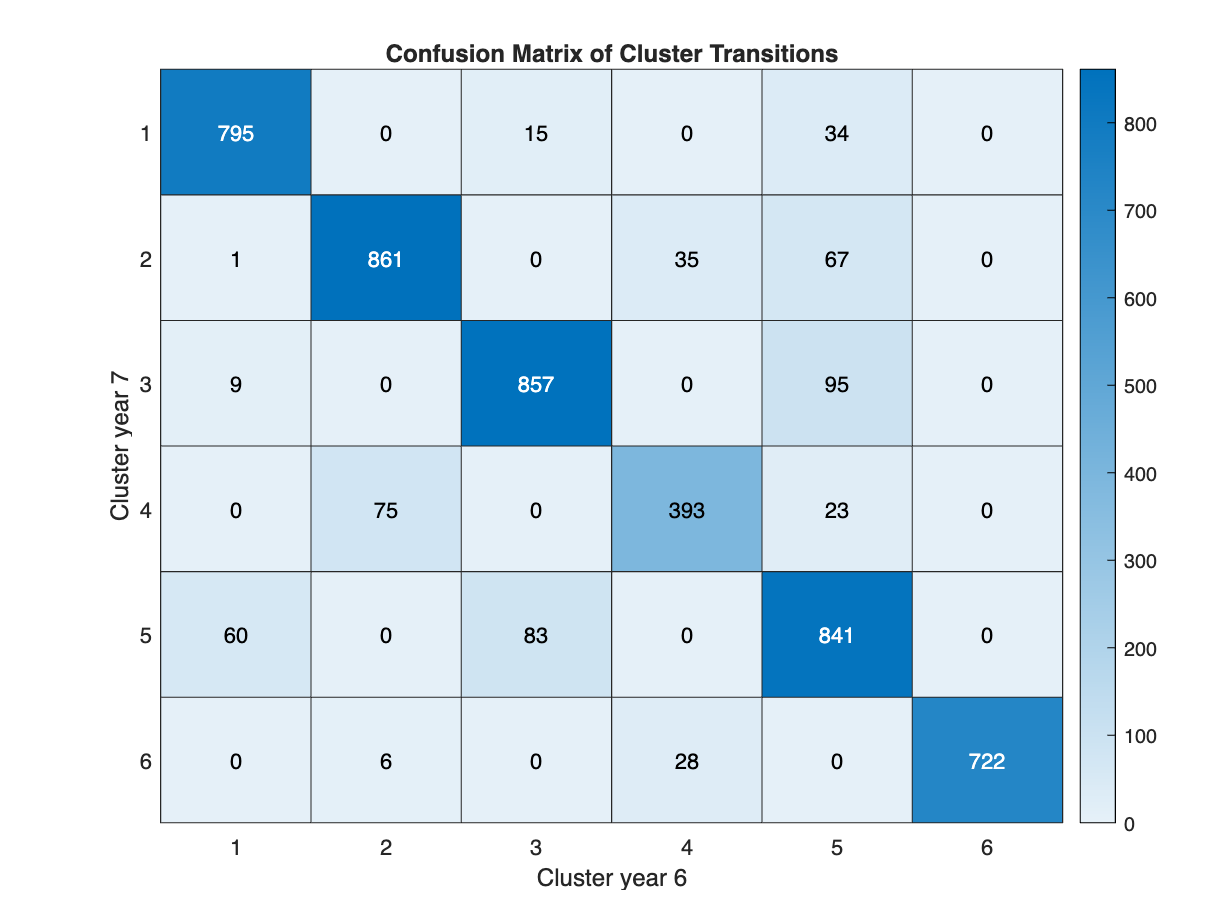

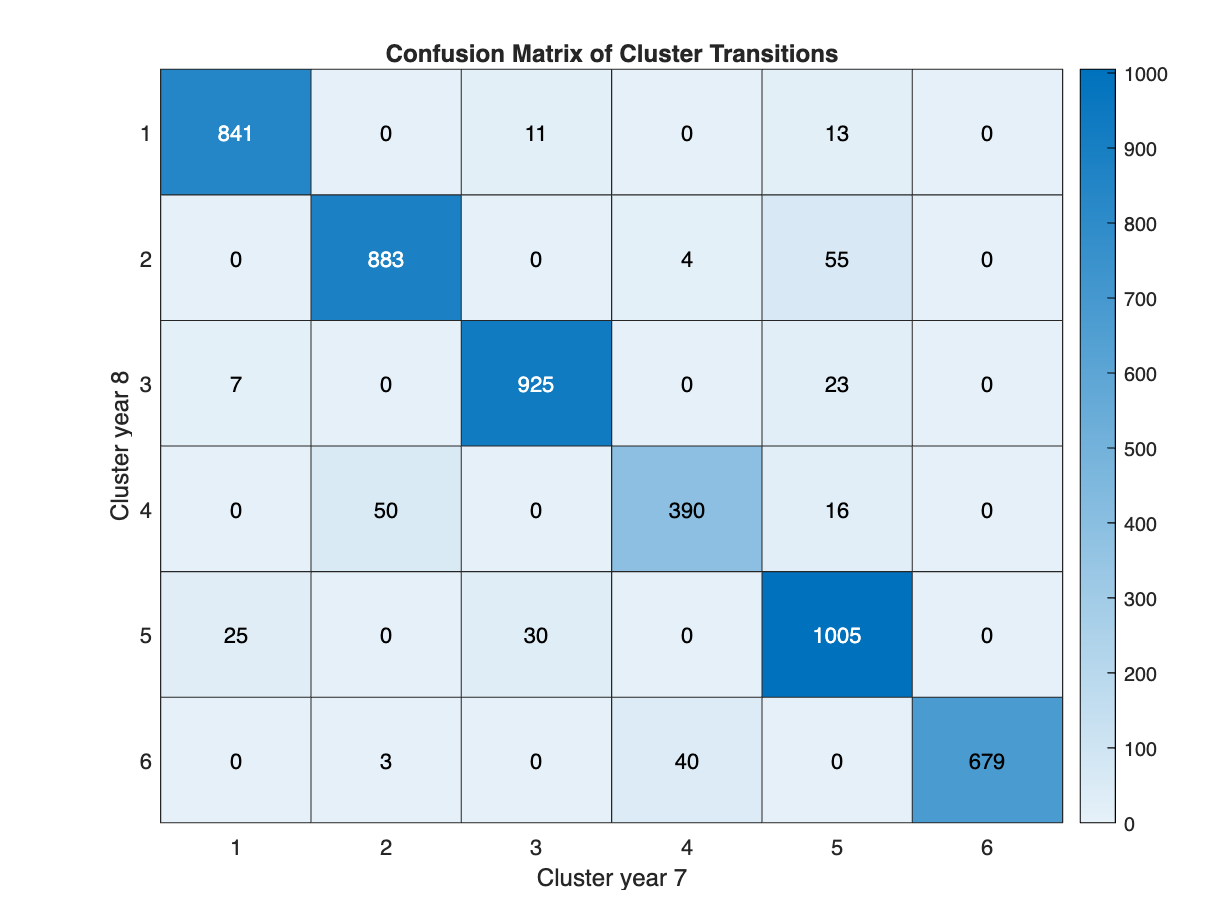

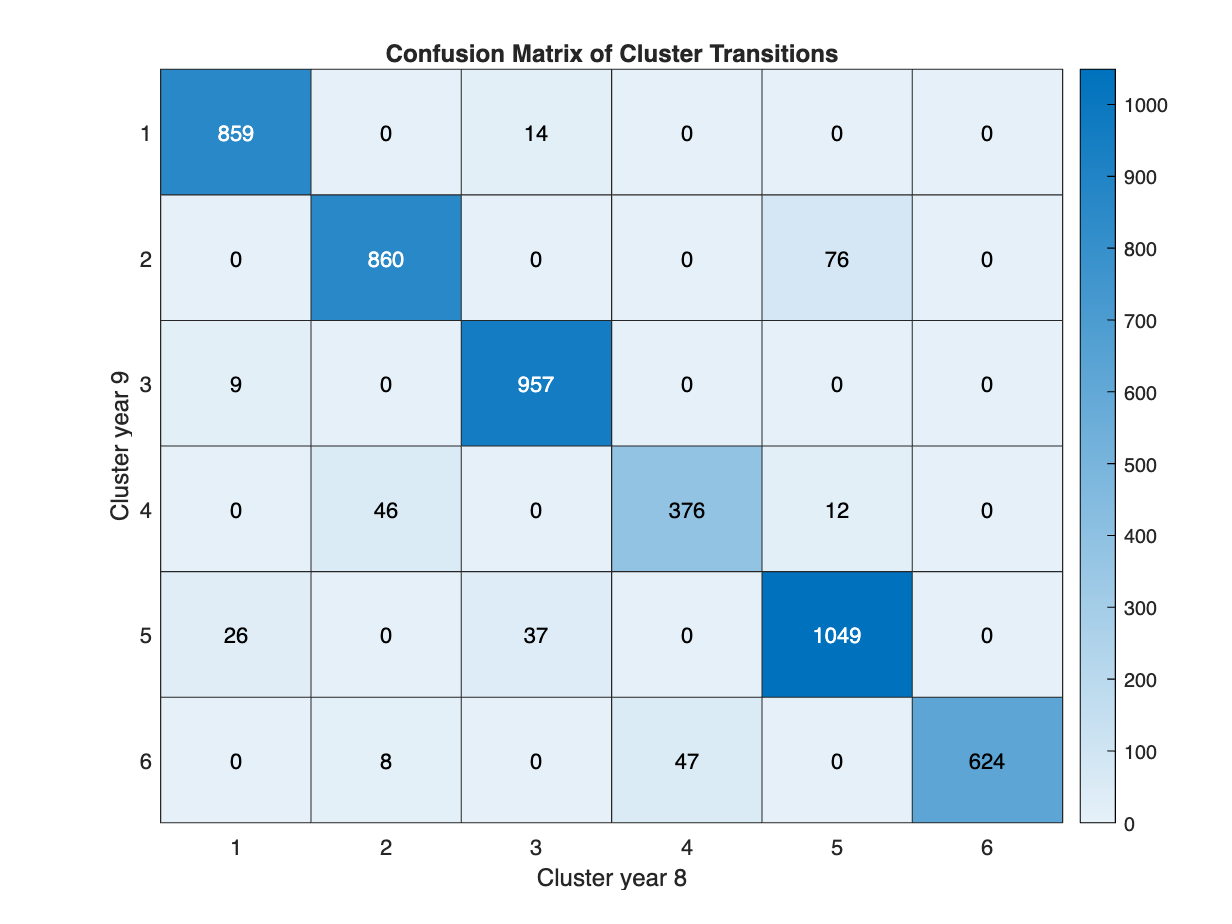

for i=1:tot_years-1
    confusion_matrix = confusionmat(progr_clusts(:,i), progr_clusts(:,i+1));
    figure;
    heatmap(confusion_matrix, 'XLabel', sprintf('Cluster year %d', i), 'YLabel', ...
    sprintf('Cluster year %d', i+1), 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'1', '2','3','4','5','6'},...
    'YDisplayLabels', {'1', '2','3','4','5','6'});
end

#### V2 VANILLA (AGE + 1,2,3,....,10; INCOME + SLOPE OF THE MODEL + NOISE)

BankClients_evo=BankClients;
progr_clusts = zeros(5000, 10);

inv_coeff=8;

tot_years=10

for yrs=1:tot_years
    BankClients_age.Age=BankClients_age.Age+1;
    progr_clusts(:,yrs)=compute_new_cluster_coeffinv(BankClients_age, centers, inv_coeff/(2^yrs));
end



clust5y_0_8_alive=clust5y_0_8.*alive_5y;

% Crea la matrice di confusione
confusion_matrix = confusionmat(clust, clust5y_0_8_alive);

% Visualizza la matrice di confusione
figure;
heatmap(confusion_matrix, 'XLabel', 'Cluster Finale', 'YLabel', ...
    'Cluster Iniziale', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'0', '1', '2','3','4','5','6'},...
    'YDisplayLabels', {'0', '1', '2','3','4','5','6'});

Se facessi con il peso a old_weight/20?

clust5y_0_4=compute_new_cluster_coeffinv(BankClients5y, centers, 0.4);

% quanti cambiano da cluster originali aggiungendo 5 anni e diminuendo il
% peso a 0.8?
diff_clusters = clust~=clust5y_0_4;
sum(diff_clusters)

clust5y_0_4_alive=clust5y_0_4.*alive_5y;

% Crea la matrice di confusione
confusion_matrix = confusionmat(clust, clust5y_0_4_alive);

% Visualizza la matrice di confusione
figure;
heatmap(confusion_matrix, 'XLabel', 'Cluster Finale', 'YLabel', ...
    'Cluster Iniziale', 'Title', 'Confusion Matrix of Cluster Transitions',...
    'XDisplayLabels', {'0', '1', '2','3','4','5','6'},...
    'YDisplayLabels', {'0', '1', '2','3','4','5','6'});

## FUNZIONI USATE NEL CODICE

function center = compute_center(cluster)
% Calcola il centro del cluster come media dei valori numerici e moda di
% valori categorici
    dim=size(cluster,2);
    center=zeros(dim,1);
    for i = 2:dim
        if (i >= 3 && i <= 6) || i==18
           center(i,1) = mode(table2array(cluster(:,i)));
        else 
            center(i,1)= mean(table2array(cluster(:,i)));
        end
        center(2,1)=round(center(2,1));
        center(7,1)=round(center(7,1));
    end
end


function T = get_death_probability(age, gender, fem_probs, man_probs)
% creo T che alla fine mi genera vivo 1 o morto 0 in base alle prob
    T=ones(size(age,1),1);
    for i = 1:size(T,1)
        prob = 0; % Default probability
        for r = 1:size(fem_probs,1)
            if age(i,1) >= fem_probs(r,1) && age(i,1) <= fem_probs(r, 2)
                if gender(i,1)== 1
                    prob = fem_probs(r, 3);
                else 
                    prob = man_probs(r, 3);
                end
                break;
            end
        end
        T(i,1)=rand() > prob;
    end
end

function T_new=compute_new_cluster(BankClients_evolved, centers)
% calcola il centro più vicino a quel punto e assegna il punto al cluster
% del centro
    names=BankClients_evolved.Properties.VariableNames;
    centers_tab=array2table(centers, 'VariableNames',names); 
    centers_tab.Gender=categorical(centers_tab.Gender);
    centers_tab.Job=categorical(centers_tab.Job);
    centers_tab.Area=categorical(centers_tab.Area);
    centers_tab.CitySize=categorical(centers_tab.CitySize);
    centers_tab.Investments=categorical(centers_tab.Investments);
    % trasformo i centri come ho fatto le X 
    % Exclude 1st col = ID
    Data_cent = [centers_tab(:,2:18); BankClients_evolved(:,2:end)];
    % Numerical
    N = vartype('numeric');
    NumFeatures = Data_cent(:,N); % subtable of numerical features
    XNum = NumFeatures.Variables; % create a matrix 
    XNum = rescale(XNum); % normalize in [0, 1]
    % Categorical
    C = vartype('categorical');
    CatFeatures = Data_cent(:,C); % subtable of categorical features  
    % Encoding (ie create dummy variables)
    %grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
    XCat = [];
    for i = 1:size(CatFeatures, 2)
        XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
        XCat = [XCat XCat_i(:,1:end)]; % To use the dummy variables in a model, we must delete a column
                % ABBIAMO DECISO DI TENERE ANCHE L'ULTIMA COLONNA DELLE DUMMY
    end   
    XC = [XCat XNum];  
    % ora mi serve una funzione che variate le caratteristiche
    % dei clienti calcoli il centro del cluster a cui 
    % sono diventati più vicini, per vedere se lo cambiano 
    Dtot=pdist(XC, @MixDistanceL2copia); 
    Dtotsq=squareform(Dtot);  
    % calcolo il più vicino dei centri ad ogni punto    
    Duseful=Dtotsq(1:6,7:5006);
    [~, T_new] = min(Duseful);
    T_new=transpose(T_new);
end

% METTO IL PESO MODIFICABILE 

function T_new=compute_new_cluster_coeffinv(BankClients_evolved, centers, coeffinv)
% calcola il centro più vicino a quel punto e assegna il punto al cluster
% del centro
    names=BankClients_evolved.Properties.VariableNames;
    centers_tab=array2table(centers, 'VariableNames',names); 
    centers_tab.Gender=categorical(centers_tab.Gender);
    centers_tab.Job=categorical(centers_tab.Job);
    centers_tab.Area=categorical(centers_tab.Area);
    centers_tab.CitySize=categorical(centers_tab.CitySize);
    centers_tab.Investments=categorical(centers_tab.Investments);
    % trasformo i centri come ho fatto le X 
    % Exclude 1st col = ID
    Data_cent = [centers_tab(:,2:18); BankClients_evolved(:,2:end)];
    % Numerical
    N = vartype('numeric');
    NumFeatures = Data_cent(:,N); % subtable of numerical features
    XNum = NumFeatures.Variables; % create a matrix 
    XNum = rescale(XNum); % normalize in [0, 1]
    % Categorical
    C = vartype('categorical');
    CatFeatures = Data_cent(:,C); % subtable of categorical features  
    % Encoding (ie create dummy variables)
    %grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
    XCat = [];
    for i = 1:size(CatFeatures, 2)
        XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
        XCat = [XCat XCat_i(:,1:end)]; % To use the dummy variables in a model, we must delete a column
                % ABBIAMO DECISO DI TENERE ANCHE L'ULTIMA COLONNA DELLE DUMMY
    end   
    XC = [XCat XNum];  
    % ora mi serve una funzione che variate le caratteristiche
    % dei clienti calcoli il centro del cluster a cui 
    % sono diventati più vicini, per vedere se lo cambiano 
    dist_coeffinv=@(X,Y)MixDistanceL2copia_coeffinv(X,Y,coeffinv);
    Dtot=pdist(XC, dist_coeffinv); 
    Dtotsq=squareform(Dtot);  
    % calcolo il più vicino dei centri ad ogni punto    
    Duseful=Dtotsq(1:6,7:5006);
    [~, T_new] = min(Duseful);
    T_new=transpose(T_new);
end
